fid = fopen('hw1p4_data.csv');

readData = textscan(fid,'%f %f %f','Delimiter',',');

X = readData{1,1}(:,1);
Y = readData{1,2}(:,1);
Z = readData{1,3}(:,1);

Scatter Plots:

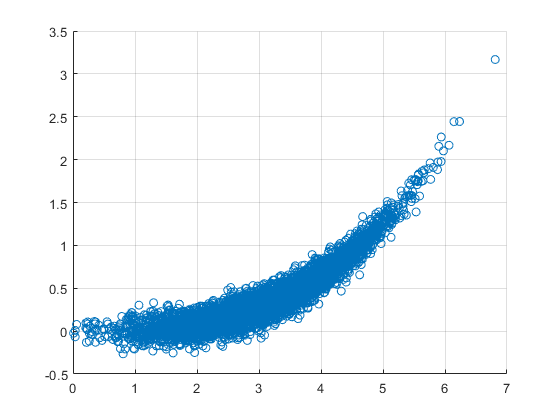

cla; hold on; grid on;
scatter(X,Y);

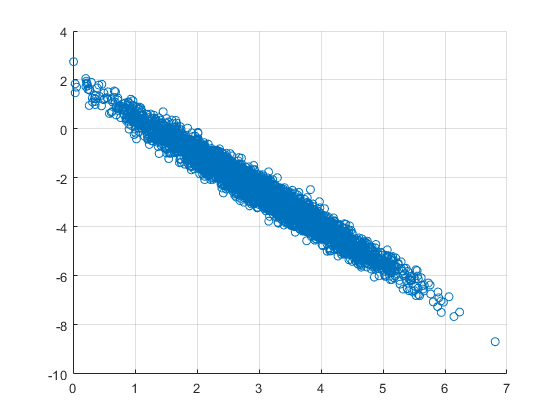

cla; hold on; grid on;
scatter(X,Z);

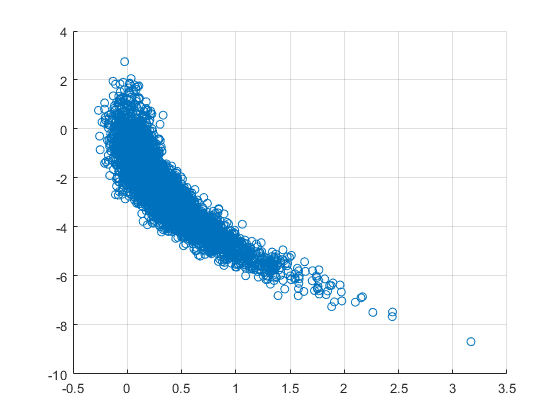

cla; hold on; grid on;
scatter(Y,Z);


N = numel(X);
CovXY = (X-mean(X))'*(Y-mean(Y))/(N-1);
CovYX = CovXY;
CovXZ = (X-mean(X))'*(Z-mean(Z))/(N-1);
CovZX = CovXZ;
CovYZ = (Y-mean(Y))'*(Z-mean(Z))/(N-1);
CovZY = CovYZ;

Mean = [mean(X); mean(Y); mean(Z)]

Mean =     3.0323
    0.3687
   -2.5519


CovMx = [var(X) CovXY CovXZ;
         CovYX  var(Y) CovYZ;
         CovZX  CovZY  var(Z)]

CovMx =     0.9714    0.2922   -1.4537
    0.2922    0.1133   -0.4371
   -1.4537   -0.4371    2.2644


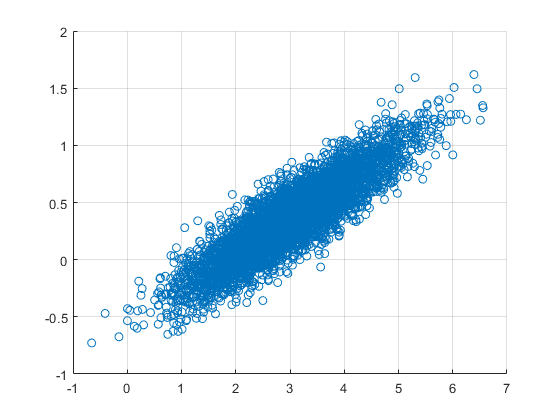

     
rng('default');
R = mvnrnd(Mean,CovMx,N);

cla; hold on; grid on;
scatter(R(:,1),R(:,2));

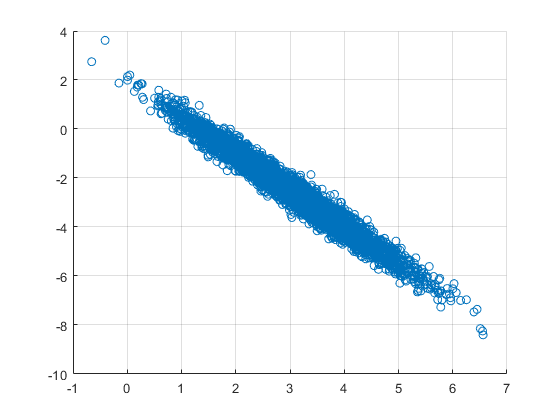

cla; hold on; grid on;
scatter(R(:,1),R(:,3));

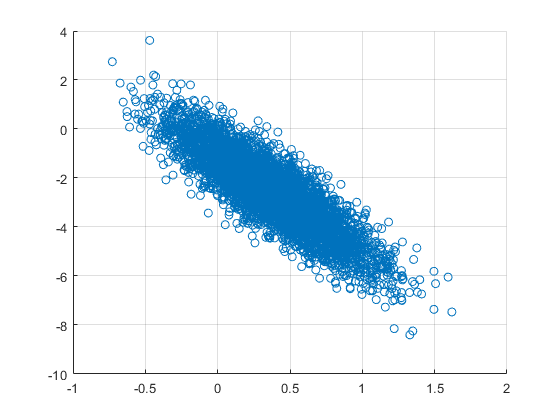

cla; hold on; grid on;
scatter(R(:,2),R(:,3));

A = [1 2;2 5;3 6;4 7;5 1];
sum(A,2)

ans =      3
     7
     9
    11
     6


Question 5.

fid = fopen('hw1p5_data.csv');

readData = textscan(fid,'%f %f','Delimiter',',');

X = readData{1,1}(:,1);
Y = readData{1,2}(:,1);
N = numel(X);

data = [X Y];

% cla; hold on; grid on;
% plot(X,Y,'b-')

[Train,idx] = datasample(data,10);
T = data;
T(idx,:) = [];

% matrix = [1 2 3;3 4 6;3 5 8;9 5 2; 6 9 0]
% [train,idx] = datasample(matrix,2)
% matrix(idx,:) = []

% [p,S] = polyfit(Train(:,1),Train(:,1),1);
% fitY = polyval(p,T(:,1));
% MSE = (sum((fitY - T(:,2)).^2))/N
% cla; hold on; grid on;
% plot(T(:,1),T(:,2),'r-');
% plot(T(:,1),fitY,'b-');

for i = 1:2
    MSE = 0;
    n = i
    for j = 1:100
        [train,idx] = datasample(data,10);
        t = data;
        t(idx,:) = [];
        
        [p,S] = polyfit(train(:,1),train(:,1),i);
        fitY = polyval(p,t(:,1));
        MSE = MSE + (sum((fitY - t(:,2)).^2))/N;
    end
%     cla; hold on; grid on;
%     plot(t(:,1),t(:,2),'r-');
%     plot(t(:,1),sum(Ytest,2)/100,'b-');
    MSE = MSE/100
end

n = 1